Alen Mehmedbegovic - 301476021

Feburary 4th, 2024

Question 1

% Added three more sets of images, each with at least 4 images.

Question 2

Image1S1 = imread("S1-im1.png");
Image1S2 = imread("S2-im1.JPEG");

detectedcornersS1im1 = fastdetector(Image1S1, 33);
detectedcornersS2im1 = fastdetector(Image1S2, 50);

ImageS1im1detectedcorners = imoverlay(Image1S1, detectedcornersS1im1);
ImageS2im1detectedcorners = imoverlay(Image1S2, detectedcornersS2im1);

imwrite(ImageS1im1detectedcorners, "S1-fast.png");
imwrite(ImageS2im1detectedcorners, "S2-fast.png");

% Harris cornerness measure
detectedcornersS1im1H = harriscornerness(detectedcornersS1im1, 0.05);
detectedcornersS2im1H = harriscornerness(detectedcornersS2im1, 0.04);

ImageS1im1detectedcornersH = imoverlay(Image1S1, detectedcornersS1im1H);
ImageS2im1detectedcornersH = imoverlay(Image1S2, detectedcornersS2im1H);

imwrite(ImageS1im1detectedcornersH, "S1-fastR.png");
imwrite(ImageS2im1detectedcornersH, "S2-fastR.png");

Question 3

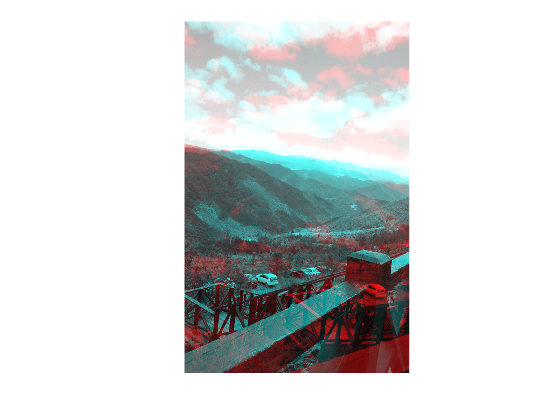

% Convert the detected corners to grayscale images
Image1S1detectedcornersgrey = im2gray(detectedcornersS1im1);
Image1S2detectedcornersgrey = im2gray(detectedcornersS2im1);

% Use detectSURFFeatures on the grayscale images
SURFpointsimageS1im1fast = detectSURFFeatures(Image1S1detectedcornersgrey);
SURFpointsimageS2im1fast = detectSURFFeatures(Image1S2detectedcornersgrey);

% Repeat the process for detectedcornersH
ImageS1im1detectedcornersHgrey = im2gray(detectedcornersS1im1H);
ImageS2im1detectedcornersHgrey = im2gray(detectedcornersS2im1H);

SURFpointsimageS1im1Hfast = detectSURFFeatures(ImageS1im1detectedcornersHgrey);
SURFpointsimageS2im1Hfast = detectSURFFeatures(ImageS2im1detectedcornersHgrey);

% Now, we also need the points of the corresponding set's second
% image
Image2S1 = imread("S1-im2.png");
Image2S2 = imread("S2-im2.JPEG");

detectedcornersS1im2 = fastdetector(Image2S1, 33);
detectedcornersS2im2 = fastdetector(Image2S2, 50);

ImageS1im2detectedcorners = imoverlay(Image2S1, detectedcornersS1im2);
ImageS2im2detectedcorners = imoverlay(Image2S2, detectedcornersS2im2);

% Harris cornerness measure
detectedcornersS1im2H = harriscornerness(detectedcornersS1im2, 0.05);
detectedcornersS2im2H = harriscornerness(detectedcornersS2im2, 0.04);

ImageS1im2detectedcornersH = imoverlay(Image2S1, detectedcornersS1im2H);
ImageS2im2detectedcornersH = imoverlay(Image2S2, detectedcornersS2im2H);

% Convert the detected corners to grayscale images
Image2S1detectedcornersgrey = im2gray(detectedcornersS1im2);
Image2S2detectedcornersgrey = im2gray(detectedcornersS2im2);

% Use detectSURFFeatures on the grayscale images
SURFpointsimageS1im2fast = detectSURFFeatures(Image2S1detectedcornersgrey);
SURFpointsimageS2im2fast = detectSURFFeatures(Image2S2detectedcornersgrey);

% Repeat the process for detectedcornersH
ImageS1im2detectedcornersHgrey = im2gray(detectedcornersS1im2H);
ImageS2im2detectedcornersHgrey = im2gray(detectedcornersS2im2H);

SURFpointsimageS1im2Hfast = detectSURFFeatures(ImageS1im2detectedcornersHgrey);
SURFpointsimageS2im2Hfast = detectSURFFeatures(ImageS2im2detectedcornersHgrey);

% Now let's map and match
[featuresS1im1, positionsS1im1] = extractFeatures(rgb2gray(Image1S1), SURFpointsimageS1im1fast);
[featuresS1im2, positionsS1im2] = extractFeatures(rgb2gray(Image2S1), SURFpointsimageS1im2fast);

indexPairsS1 = matchFeatures(featuresS1im1,featuresS1im2) ;

matchedPointsS1im1 = positionsS1im1(indexPairsS1(:,1));
matchedPointsS1im2 = positionsS1im2(indexPairsS1(:,2));

saveas(showMatchedFeatures(rgb2gray(Image1S1), rgb2gray(Image2S1), matchedPointsS1im1, matchedPointsS1im2), "S1-fastMatch.png");



[featuresS1im1H, positionsS1im1H] = extractFeatures(rgb2gray(Image1S1), SURFpointsimageS1im1Hfast);
[featuresS1im2H, positionsS1im2H] = extractFeatures(rgb2gray(Image2S1), SURFpointsimageS1im2Hfast);

indexPairsS1H = matchFeatures(featuresS1im1H, featuresS1im2H) ;

matchedPointsS1im1H = positionsS1im1H(indexPairsS1H(:,1));
matchedPointsS1im2H = positionsS1im2H(indexPairsS1H(:,2));

saveas(showMatchedFeatures(rgb2gray(Image1S1), rgb2gray(Image2S1), matchedPointsS1im1H, matchedPointsS1im2H), "S1-fastRMatch.png");


[featuresS2im1, positionsS2im1] = extractFeatures(rgb2gray(Image1S2), SURFpointsimageS2im1fast);
[featuresS2im2, positionsS2im2] = extractFeatures(rgb2gray(Image2S2), SURFpointsimageS2im2fast);

indexPairsS2 = matchFeatures(featuresS2im1, featuresS2im2) ;

matchedPointsS2im1 = positionsS2im1(indexPairsS2(:,1));
matchedPointsS2im2 = positionsS2im2(indexPairsS2(:,2));

saveas(showMatchedFeatures(rgb2gray(Image1S2), rgb2gray(Image2S2),matchedPointsS2im1,matchedPointsS2im2), "S2-fastMatch.png");


[featuresS2im1H, positionsS2im1H] = extractFeatures(rgb2gray(Image1S2), SURFpointsimageS2im1Hfast);
[featuresS2im2H, positionsS2im2H] = extractFeatures(rgb2gray(Image2S2), SURFpointsimageS2im2Hfast);

indexPairsS2H = matchFeatures(featuresS2im1H, featuresS2im2H) ;

matchedPointsS2im1H = positionsS2im1H(indexPairsS2H(:,1));
matchedPointsS2im2H = positionsS2im2H(indexPairsS2H(:,2));

saveas(showMatchedFeatures(rgb2gray(Image2S2), rgb2gray(Image2S2), matchedPointsS2im1H, matchedPointsS2im2H), "S2-fastRMatch.png");

Question 4

% I will follow the MATLAB implementation of image stitching 
% https://www.mathworks.com/help/vision/ug/feature-based-panoramic-image-stitching.html
% Look at EOF for function implementation
% step 1 
% Load images.
% For S1, we need the most at about 100
% For S2, 20 trials will give an acceptable result
% For S3, about 30 trials will give an acceptable result
% For S4, alot of detail is here so we need alot more trials. About 50
% Let's just use 100 for all of them, we don't need more than 30 for S2 &
% S3 and 50 for S4.

S1Dir = fullfile("Part 4 images/S1");
S1Scene = imageDatastore(S1Dir);
panorama1 = stitch(S1Scene, 100, 40, 0.05);
imwrite(panorama1, "S1-panorama.png");

S2Dir = fullfile("Part 4 images/S2");
S2Scene = imageDatastore(S2Dir);
panorama2 = stitch(S2Scene, 100, 40, 0.05);
imwrite(panorama2, "S2-panorama.png");

S3Dir = fullfile("Part 4 images/S3");
S3Scene = imageDatastore(S3Dir);
panorama3 = stitch(S3Scene, 100, 40, 0.05);
imwrite(panorama3, "S3-panorama.png");

S4Dir = fullfile("Part 4 images/S4");
S4Scene = imageDatastore(S4Dir);
panorama4 = stitch(S4Scene, 100, 40, 0.05);
imwrite(panorama4, "S4-panorama.png");

Question 5 (Bonus) 

% It takes too long to do 4 images :(

Question 2 function(s) defintion 

function detectedcorners = fastdetector(image, threshold)
% Following openCV website implementation "Feature Detection using FAST"

image = rgb2gray(image); % Convert to "intensity map"
[rows, cols] = size(image);
detectedcorners = zeros(rows, cols);    % Image sized logical matrix of all zeroes 
circlecornersbelow = zeros(1,16); % Used for identifying pixels below intensities range 
circlecornersabove = zeros(1,16); % Used for identifying pixels above intensities range 
highspeedtestcounterlow = 0;
highspeedtestcounterhigh = 0;

% Since our FAST detector will examine a circle of radius 3, we can't 
    % examine pixels which would have the circle go beyond the image borders.
    for i = 4:rows-3
        for j = 4:cols-3
        Ip = image(i,j); % Step 1 
        thresholdrange = [Ip - threshold, Ip + threshold]; % Step 2 
        brecircle = bresenhamcirclerad3(i,j); % Step 3 
       
        % Step 4 
            for k = 1:2:31
                % if the intensity of circle pixel is not in the threshold
                if (~(image(brecircle(k), brecircle(k + 1)) > thresholdrange(1)) && (image(brecircle(k), brecircle(k + 1)) < thresholdrange(2)))  
                    % If it's below the range
                    if(image(brecircle(k), brecircle(k + 1)) < thresholdrange(1))
                        circlecornersbelow(ceil(k/2)) = 1;
                    else
                    % If it's above
                        circlecornersabove(ceil(k/2)) = 1;
                    end
                end
            end
        % Now that we've classified our threshold detectedcorners in the corners
        % matrices, we have to check for contiguous values 
            if(contiguousarc(circlecornersabove) || contiguousarc(circlecornersbelow))
                detectedcorners(i,j) = 1;
                % Step 5: high-speed test
                pixel1 = [brecircle(1), brecircle(2)];
                pixel5 = [brecircle(9), brecircle(10)];
                pixel9 = [brecircle(17), brecircle(18)];
                pixel13 = [brecircle(25), brecircle(26)];
                % According to openCV implementation, first test 1 & 9
                if(image(pixel1(1), pixel1(2)) < thresholdrange(1)) % Check if pixel 1 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                end
                if(image(pixel1(1), pixel1(2)) > thresholdrange(2)) % Check if pixel 1 is lighter than threshold
                    highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                end
                if(image(pixel9(1), pixel9(2)) < thresholdrange(1)) % Check if pixel 9 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                end
                if(image(pixel9(1), pixel9(2)) > thresholdrange(2)) % Check if pixel 9 is lighter than threshold
                    highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                end
                % Now test pixel 5 and 13
                if((highspeedtestcounterlow > 0) || (highspeedtestcounterhigh > 0)) % If we have at least 1 or 9 be yes
                    if(image(pixel5(1), pixel5(2)) < thresholdrange(1)) % Check if pixel 5 is darker than threshold
                    highspeedtestcounterlow = highspeedtestcounterlow + 1;
                    end
                    if(image(pixel5(1), pixel5(2)) > thresholdrange(2)) % Check if pixel 5 is lighter than threshold
                        highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                    end
                    if(image(pixel13(1), pixel13(2)) < thresholdrange(1)) % Check if pixel 13 is darker than threshold
                        highspeedtestcounterlow = highspeedtestcounterlow + 1;
                    end
                    if(image(pixel13(1), pixel13(2)) > thresholdrange(2)) % Check if pixel 9 is lighter than threshold
                        highspeedtestcounterhigh = highspeedtestcounterhigh + 1;
                    end
                end
                if(~((highspeedtestcounterhigh > 2) || (highspeedtestcounterlow > 2))) % If they're not at least 3
                    detectedcorners(i,j) = 0;
                end
                highspeedtestcounterlow = 0;
                highspeedtestcounterhigh = 0;
            end
        end
    end 
end

% Function for finding bresenhamcircle radius 3 at (x,y)
% Returns a 1x32 matrix that represent the positions of the x,y indices 
function brecirclerad3 = bresenhamcirclerad3(x,y)
    % I am not smart enough to do this alghorithmically, so lets do it
    % manually 
    brecirclerad3 = [x - 3, y]; % 1
    brecirclerad3 = [brecirclerad3, [x - 3, y + 1]]; % 2
    brecirclerad3 = [brecirclerad3, [x - 2, y + 2]]; % 3
    brecirclerad3 = [brecirclerad3, [x - 1, y + 3]]; % 4
    brecirclerad3 = [brecirclerad3, [x, y + 3]]; % 5
    brecirclerad3 = [brecirclerad3, [x + 1, y + 3]]; % 6
    brecirclerad3 = [brecirclerad3, [x + 2, y + 2]]; % 7
    brecirclerad3 = [brecirclerad3, [x + 3, y + 1]]; % 8
    brecirclerad3 = [brecirclerad3, [x + 3, y]]; % 9
    brecirclerad3 = [brecirclerad3, [x + 3, y - 1]]; % 10
    brecirclerad3 = [brecirclerad3, [x + 2, y - 2]]; % 11
    brecirclerad3 = [brecirclerad3, [x + 1, y - 3]]; % 12
    brecirclerad3 = [brecirclerad3, [x, y - 3]]; % 13
    brecirclerad3 = [brecirclerad3, [x - 1, y - 3]]; % 14
    brecirclerad3 = [brecirclerad3, [x - 2, y - 2]]; % 15
    brecirclerad3 = [brecirclerad3, [x - 3, y - 1]]; % 16
end

function hasarc = contiguousarc(circlecornersmatrix)
    circlecornersmatrix = [circlecornersmatrix, circlecornersmatrix];  % Concatenate with itself to simulate circular array
    hasarc = 0;     % Default value is zero
    maxlength = 0;
    currentlength = 0;

    for i = 1:length(circlecornersmatrix)
        if circlecornersmatrix(i) == 1
            currentlength = currentlength + 1;
            if currentlength > maxlength
                maxlength = currentlength;  
            end
        else
            currentlength = 0;
        end
        if maxlength >= 12
            hasarc = 1;
            return;
        end
    end
end

function R = harriscornerness(I,k)
    % Get Ix and Iy from dog kernel
    sob = [-1 0 1; -2 0 2; -1 0 1];
    gauss = fspecial('gaussian', 3, 1);
    dog = conv2(gauss, sob);
    Ix = imfilter(I, dog);
    Iy = imfilter(I, dog');

    Ix2 = imgaussfilt(Ix.^2, 1);
    Iy2 = imgaussfilt(Iy.^2, 1);
    Ixy = imgaussfilt(Ix.*Iy, 1);

    % R = detM - k*(trM)^2;
    R = (Ix2.*Iy2 - Ixy.^2) - k*(Ix2+Iy2).^2;
    % Get rid of all negative elements
    R(R < 0) = 0;
end

% Part 4 stitch function
function panorama = stitch(scene, ransacparameter, fastthreshold, harristhreshold)
% Read the first image from the image set.
I = readimage(scene,1);

% Initialize features for I(1)
grayImage = im2gray(I);
points = fastdetector(I, fastthreshold);
points = harriscornerness(points, harristhreshold);
points = detectSURFFeatures(points);
[features, points] = extractFeatures(grayImage,points);

% Initialize all the transformations to the identity matrix. Note that the
% projective transformation is used here because the building images are fairly
% close to the camera. For scenes captured from a further distance, you can use
% affine transformations.
numImages = numel(scene.Files);
tforms(numImages) = projtform2d;

% Initialize variable to hold image sizes.
imageSize = zeros(numImages,2);

% Iterate over remaining image pairs
    for n = 2:numImages
        % Store points and features for I(n-1).
        pointsPrevious = points;
        featuresPrevious = features;
            
        % Read I(n).
        I = readimage(scene, n);
        
        % Convert image to grayscale.
        grayImage = im2gray(I);    
        
        % Save image size.
        imageSize(n,:) = size(grayImage);
        
        % Detect and extract SURF features for I(n).
        points = fastdetector(I, fastthreshold);
        points = harriscornerness(points, harristhreshold);
        points = detectSURFFeatures(points);    
        [features, points] = extractFeatures(grayImage, points);

        % Find correspondences between I(n) and I(n-1).
        indexPairs = matchFeatures(features, featuresPrevious, 'Unique', true);
           
        matchedPoints = points(indexPairs(:,1), :);
        matchedPointsPrev = pointsPrevious(indexPairs(:,2), :);        
        
        % Estimate the transformation between I(n) and I(n-1).
        % This is where we alter our RANSAC parameter 
        tforms(n) = estgeotform2d(matchedPoints, matchedPointsPrev,...
            'projective', 'Confidence', 99.9, 'MaxNumTrials', ransacparameter);
        
        % Compute T(1) * T(2) * ... * T(n-1) * T(n).
        tforms(n).A = tforms(n-1).A * tforms(n).A;
    end

    % Compute the output limits for each transformation.
    for i = 1:numel(tforms)           
        [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);    
    end
    avgXLim = mean(xlim, 2);
    [~,idx] = sort(avgXLim);
    centerIdx = floor((numel(tforms)+1)/2);
    centerImageIdx = idx(centerIdx);

    Tinv = invert(tforms(centerImageIdx));

    for i = 1:numel(tforms)    
        tforms(i).A = Tinv.A * tforms(i).A;
    end

    for i = 1:numel(tforms)           
        [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 imageSize(i,2)], [1 imageSize(i,1)]);
    end
    
    maxImageSize = max(imageSize);
    
    % Find the minimum and maximum output limits. 
    xMin = min([1; xlim(:)]);
    xMax = max([maxImageSize(2); xlim(:)]);
    
    yMin = min([1; ylim(:)]);
    yMax = max([maxImageSize(1); ylim(:)]);
    
    % Width and height of panorama.
    width  = round(xMax - xMin);
    height = round(yMax - yMin);
    
    % Initialize the "empty" panorama.
    panorama = zeros([height width 3], 'like', I);

    blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port');  

    % Create a 2-D spatial reference object defining the size of the panorama.
    xLimits = [xMin xMax];
    yLimits = [yMin yMax];
    panoramaView = imref2d([height width], xLimits, yLimits);
    
    % Create the panorama.
    for i = 1:numImages
        
        I = readimage(scene, i);   
       
        % Transform I into the panorama.
        warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                      
        % Generate a binary mask.    
        mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
        
        % Overlay the warpedImage onto the panorama.
        panorama = step(blender, panorama, warpedImage, mask);
    end
    
end